% -----------------------------------------------------------------
% OFDM 802.11a/g WLAN SIGNAL GENRATION WITH REFERENCE SYMBOLS 
% Angelina Abuhilal - IoTellegence Lab - UTA CSE 
% WiFi packet generation code from Naeeb Ridwan
% - MCS0 (BPSK 1/2), EXACTLY 64 DATA OFDM symbols
% - Overwrite payload with custom low correlation symbols
% - DEMO: autocorrelation testing at full sampling rate and below
% MATLAB WLAN function library https://www.mathworks.com/help/wlan/referencelist.html?type=function&s_tid=CRUX_topnav
% -----------------------------------------------------------------

clear; clc; rng(1);

if isempty(which('wlanNonHTConfig'))                    % WLAN toolbox is needed
    error('WLAN Toolbox is required for this script.');
end

% -----------------------------------------------------------------
% Packet Variables 
% -----------------------------------------------------------------

MCS  = 0;                   % 0..7
Ns   = 64;                  % number of DATA symbols
Ndbps_table = [24 36 48 72 96 144 192 216];
Ndbps = Ndbps_table(MCS+1); % number of info bits per OFDM symbol (CBW20)

% Choose PSDU length B so that ceil((16 + 8B + 6)/Ndbps) = Ns
% 22 = SERVICE(16) + TAIL(6)
minB = ceil((Ndbps * (Ns-1) + 1 - 22) / 8);
maxB = floor((Ndbps * Ns        - 22) / 8);
if maxB < minB
    error('Cannot realize exactly %d DATA symbols with MCS=%d.', Ns, MCS);
end
B = floor((minB + maxB)/2);  % PSDU length in BYTES (any B in [minB,maxB] works)

% -----------------------------------------------------------------
% Build WiFi Packet  (WLAN Toolbox Non-HT packet)
% -----------------------------------------------------------------

cfg   = wlanNonHTConfig('ChannelBandwidth','CBW20','MCS',MCS,'PSDULength',B);
fs    = wlanSampleRate(cfg);

psdu  = randi([0 1], cfg.PSDULength*8, 1, 'int8');  % random bits 

% Generate packet and field indices
tx    = wlanWaveformGenerator(psdu, cfg);
ind   = wlanFieldIndices(cfg);

% Time axis in microseconds
t_us = (0:numel(tx)-1).' / fs * 1e6;

% Resolve field names across releases
getIdx  = @(S, names) S.(names{find(isfield(S,names),1,'first')});
idxLSTF = getIdx(ind, {'LSTF','NonHTLSTF'});
idxLLTF = getIdx(ind, {'LLTF','NonHTLLTF','LTF','NonHTLTF'});
idxLSIG = getIdx(ind, {'LSIG','L_SIG','Signal','NonHTSIG','NonHTLSIG'});
idxDATA = getIdx(ind, {'Data','NonHTData','DATA','NonHT_DATA'});

% Symbol granularities
Ts_short_us = 0.8;  Ns_short = round(Ts_short_us*1e-6*fs); stfStart = idxLSTF(1); %#ok<NASGU>
Ts_ofdm_us  = 4.0;  Ns_ofdm  = round(Ts_ofdm_us*1e-6*fs);
dataStart   = idxDATA(1); dataEnd = idxDATA(2);
nDataSym    = floor((dataEnd - dataStart + 1)/Ns_ofdm);   % should be 64
assert(nDataSym == Ns, 'Expected %d DATA symbols, got %d', Ns, nDataSym);

% psdu bits are interleaved and scrambled by the wlan function so overwrite
% the bits with bits that will produce expected signals (low correlation) 

Nfft    = 64;
cpLen   = 16;                        % 0.8 us (CP time) * 20 MHz = 16 samples for CP
symSamp = Nfft + cpLen;              % 80 samples per OFDM symbol 
pilotBins = [-21 -7 7 21];           % Bins used for channel estimation 
usedBins  = [-26:-1 1:26];
dataBins  = setdiff(usedBins, pilotBins); % FIX: A and B shout have the same values in theese bins 

toIdx     = @(bins) bins + (Nfft/2) + 1;  % function makes -32..31 index to 1..64 index 

% Split data bins into disjoint sets (A uses even bins, B uses odd bins)
evenMask  = mod(dataBins,2)==0;
binsA     = dataBins(evenMask);
binsB     = dataBins(~evenMask);

% Build frequency-domain vectors XA, XB (constant-magnitude PSK on their bins)
rng(42);
XA = zeros(Nfft,1);  XB = zeros(Nfft,1);
XA(toIdx(binsA)) = exp(1j*2*pi*rand(numel(binsA),1));
XB(toIdx(binsB)) = exp(1j*2*pi*rand(numel(binsB),1));
% FIX: find the bit sequence that produces the time domain signal A and B

% IFFT to time domain, add CP, normalize energy
xA0 = ifft(ifftshift(XA), Nfft);  xB0 = ifft(ifftshift(XB), Nfft);
xA  = [xA0(end-cpLen+1:end); xA0]; xB = [xB0(end-cpLen+1:end); xB0]; % copy last 16 samples to the beginning (add CP)
xA  = xA / rms(xA);  xB = xB / rms(xB); % normalize energies 

% -----------------------------------------------------------------
% OVERWRITE THE DATA FIELD WITH A/B PATTERN 
% -----------------------------------------------------------------

pattern = 'ABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBAAAAA';
pattern = pattern(1:Ns);
% fprintf("Original Encoded Symbols: %s\n", pattern);

Original Encoded Symbols: ABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABB


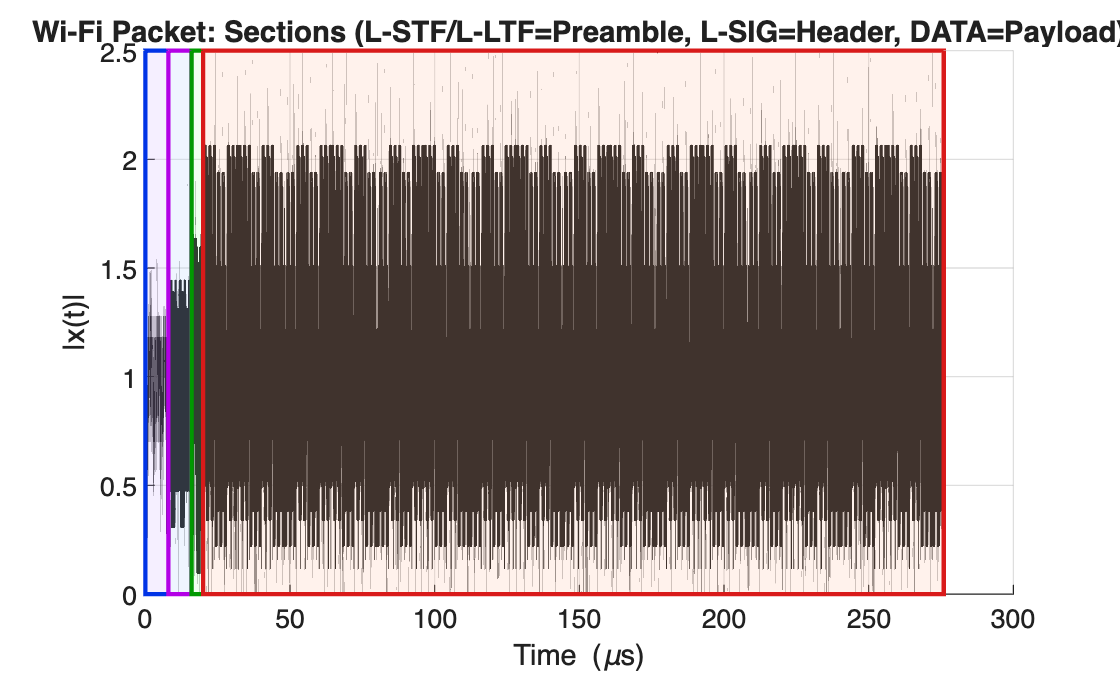


% Build concatenated DATA payload at 20 MHz
payloadTD = complex(zeros(symSamp*Ns,1)); % time domain of payload (80 samples per symbol * num of symbols)
for k = 1:Ns
    seg = ifelse(pattern(k)=='A', xA, xB);          % pattern array determines which symbol to place
    payloadTD( (k-1)*symSamp + (1:symSamp) ) = seg; % symbol placed at indexed time domain buffer
end

% Overwrite the DATA region (truncate/pad to fit exactly)
dataLen = idxDATA(2) - idxDATA(1) + 1;
payloadTD = payloadTD(1:dataLen);               % make sure correct size
tx(idxDATA(1):idxDATA(2)) = payloadTD;          % inject A/B DATA

% -----------------------------------------------------------------
% FIGURES 1 & 2: OFDM Signal in time domain  
% -----------------------------------------------------------------

fig1 = figure('Color','w','Name','FIGURE 1 — Sections (Preamble / Header / Payload)');
axF1 = axes(fig1); hold(axF1,'on'); grid(axF1,'on');
hWave = plot(axF1, t_us, abs(tx), 'k', 'LineWidth', 1.25);
xlabel(axF1,'Time (\mus)'); ylabel(axF1,'|x(t)|');
title(axF1,'Wi-Fi Packet: Sections (L-STF/L-LTF=Preamble, L-SIG=Header, DATA=Payload)');
yl = ylim(axF1);

% Colors
colLSTF_bg  = [0.85 0.75 1.00];   colLSTF_edge  = [0.00 0.20 0.90];
colLLTF_bg  = [0.75 0.85 1.00];   colLLTF_edge  = [0.70 0.00 0.90];
colLSIG_bg  = [0.75 1.00 0.75];   colLSIG_edge  = [0.00 0.60 0.00];
colDATA_bg  = [1.00 0.80 0.70];   colDATA_edge  = [0.85 0.10 0.10];
colSTF_sym  = [0.50 0.00 0.80];   % STF short-symbol boundaries (purple)
colDATA_sym = [0.85 0.10 0.10];   % DATA symbol boundaries (red)
stripColor0 = [0.80 0.88 1.00];   stripColor1 = [1.00 0.85 0.80]; %#ok<NASGU>

% Shaded backgrounds with bold edges
patch(axF1, [t_us(idxLSTF(1)) t_us(idxLSTF(2)) t_us(idxLSTF(2)) t_us(idxLSTF(1))], ...
              [yl(1) yl(1) yl(2) yl(2)], colLSTF_bg, ...
              'FaceAlpha',0.25, 'EdgeColor',colLSTF_edge, 'LineWidth',1.6);
patch(axF1, [t_us(idxLLTF(1)) t_us(idxLLTF(2)) t_us(idxLLTF(2)) t_us(idxLLTF(1))], ...
              [yl(1) yl(1) yl(2) yl(2)], colLLTF_bg, ...
              'FaceAlpha',0.25, 'EdgeColor',colLLTF_edge, 'LineWidth',1.6);
patch(axF1, [t_us(idxLSIG(1)) t_us(idxLSIG(2)) t_us(idxLSIG(2)) t_us(idxLSIG(1))], ...
              [yl(1) yl(1) yl(2) yl(2)], colLSIG_bg, ...
              'FaceAlpha',0.25, 'EdgeColor',colLSIG_edge, 'LineWidth',1.6);
patch(axF1, [t_us(idxDATA(1)) t_us(idxDATA(2)) t_us(idxDATA(2)) t_us(idxDATA(1))], ...
              [yl(1) yl(1) yl(2) yl(2)], colDATA_bg, ...
              'FaceAlpha',0.25, 'EdgeColor',colDATA_edge, 'LineWidth',1.6);

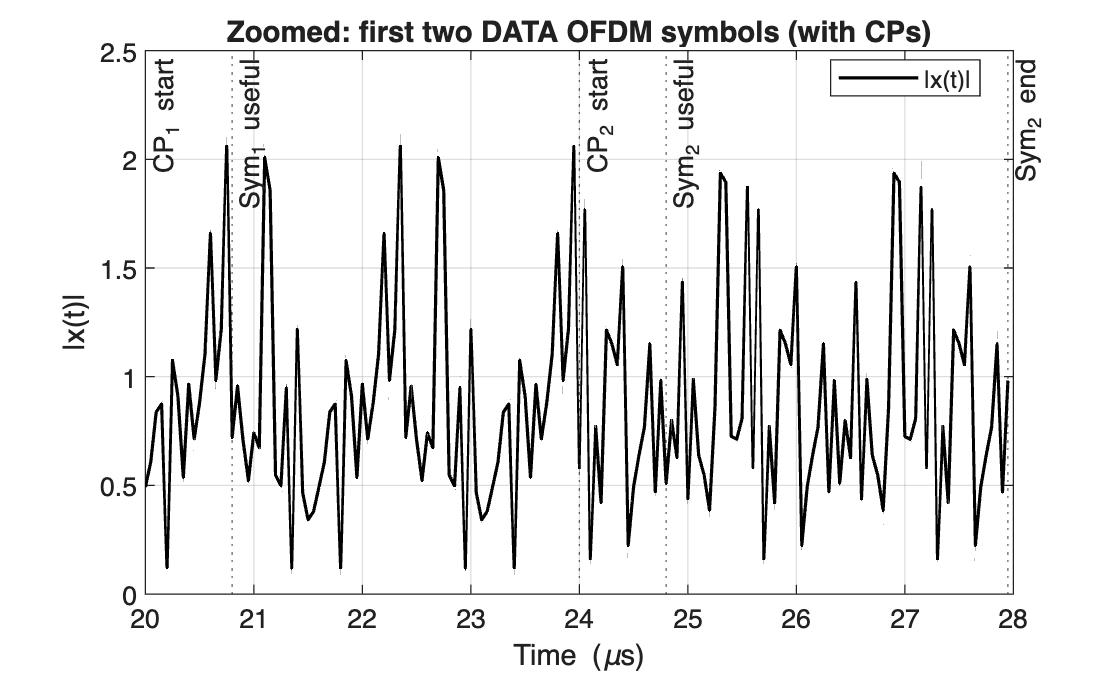


% zoomed in to first two payload symbols 
s2 = tx(idxDATA(1) : idxDATA(1) + 2*symSamp - 1);   % 2 symbols @ 20 MHz
t0_us  = t_us(idxDATA(1));                          % absolute start time (µs)
t2_us  = t0_us + (0:numel(s2)-1)'/fs*1e6;           % time axis for the zoom

figure('Color','w','Name','FIGURE Z — First two DATA symbols (zoomed)');
plot(t2_us, abs(s2), 'k', 'LineWidth', 1.2); grid on; hold on
xlabel('Time (\mus)'); ylabel('|x(t)|'); 
title('Zoomed: first two DATA OFDM symbols (with CPs)');

% Mark CP and symbol boundaries
xline(t2_us(1 + 0),   ':', 'CP_1 start');                           % start of Sym1 CP
xline(t2_us(1 + cpLen), ':', 'Sym_1 useful');                       % Sym1 useful start
xline(t2_us(1 + symSamp), ':', 'CP_2 start');                       % start of Sym2 CP
xline(t2_us(1 + symSamp + cpLen), ':', 'Sym_2 useful');             % Sym2 useful start
xline(t2_us(end),   ':', 'Sym_2 end');

legend('|x(t)|','Location','best');

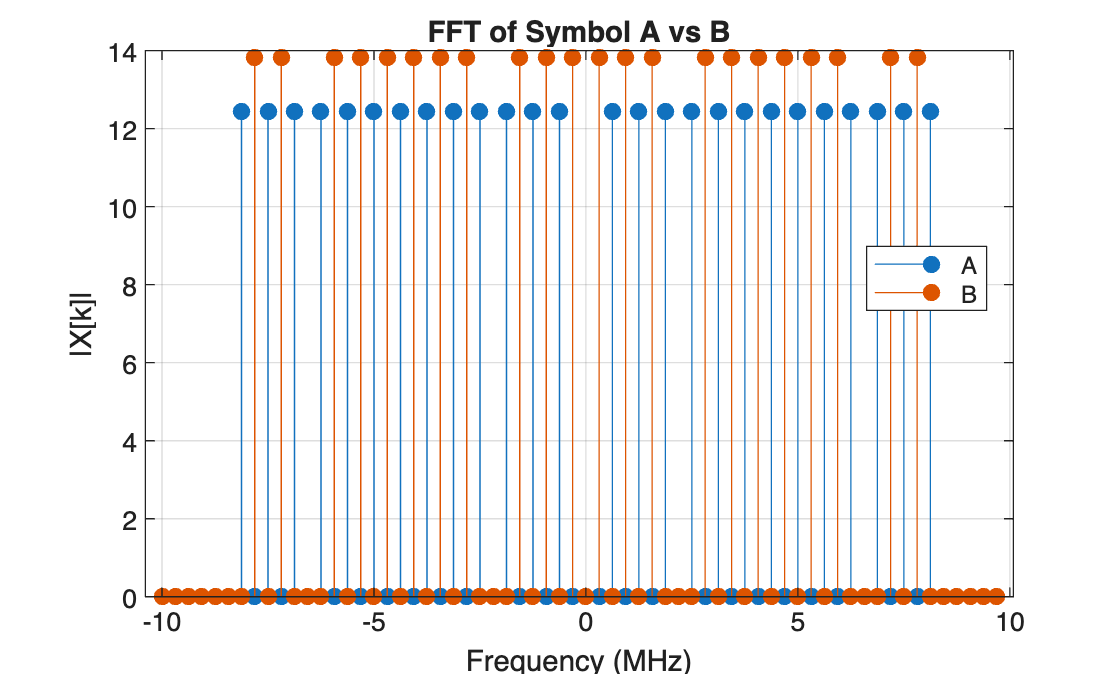


% -----------------------------------------------------------------
% FIGURES 3: Data OFDM signal in frequency domain 
% -----------------------------------------------------------------

% get only DATA slice
d = tx(idxDATA(1):idxDATA(2));
% OFDM symbol sizes
Ts_ofdm = 4e-6;  Nsym = round(Ts_ofdm*fs);        % samples per OFDM symbol
Tcp     = round(0.8e-6*fs);                       % CP length

% Take the FIRST DATA symbol
s0 = d(1:Nsym);
x_noCP = s0(Tcp+1:Tcp+Nfft);                      % remove CP
% 64-pt FFT and shift to [-fs/2, fs/2]
X = fftshift(fft(x_noCP, Nfft));

% Frequency axis per subcarrier (312.5 kHz spacing)
df = fs/Nfft;  k = (-Nfft/2:Nfft/2-1);
f_sc = k*df;   % Hz

% Take the SECOND DATA symbol
s1 = d(Nsym+1 : 2*Nsym);
x_noCP_B = s1(Tcp+1 : Tcp+Nfft);          % remove CP

% 64-pt FFT and shift to [-fs/2, fs/2]
XB = fftshift(fft(x_noCP_B, Nfft));

% A vs B overlay for quick visual comparison
figure('Color','w','Name','FIGURE 3b — A vs B (64-pt FFT magnitude)');
stem(f_sc/1e6, abs(X), 'filled'); hold on; grid on
stem(f_sc/1e6, abs(XB), 'filled');
xlabel('Frequency (MHz)'); ylabel('|X[k]|');
title('FFT of Symbol A vs B');
legend('A','B','Location','best');


% -----------------------------------------------------------------
% FIGURE 4: A & B cross-correlation check
% -----------------------------------------------------------------

% Get the correlation result and the corresponding lags
[r, lags] = xcorr(x_noCP, x_noCP_B);

% Find the index of lag 0
zeroLagIndex = find(lags == 0);

% The correlation at lag 0 is the value at this index
correlationAtZeroLag = r(zeroLagIndex);

% Plot the cross-correlation
figure;
stem(lags, r);

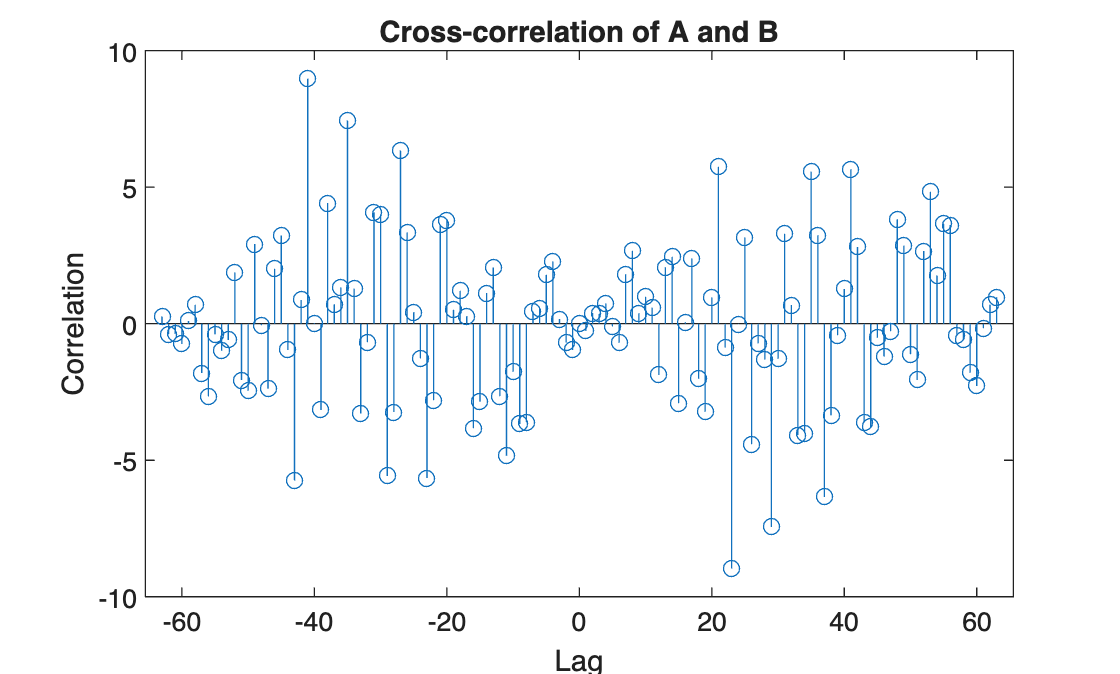

xlabel('Lag');
ylabel('Correlation');
title('Cross-correlation of A and B');


% Display the result
fprintf('The correlation when alighned is: %.2f\n', correlationAtZeroLag);

The correlation when alighned is: -0.00



% -----------------------------------------------------------------
% FIGURE 5: Reference Symbol Detection Demo 
% -----------------------------------------------------------------
% Rx SIDE: autocorrelation across the payload 
% Payload is a series of two symbols that have low correlation with each
% other. In the time domain, a lag equaling 1 symbol allows us to compare 
% the signal to itself (symbol n vs symbol n-1). Peaks in autocorrelation 
% determine that the symbol is the same as the previous symbol. Knowing 
% that the first symbol is always A allows the rest of the patter to be 
% decoded. 

symMat = reshape(d, symSamp, Ns); 
colNorm = sqrt(sum(abs(symMat).^2, 1)) + eps;
W20       = symMat ./ colNorm;

% Lag 
corrLag1_20       = nan(1, Ns);
corrLag1_20(1)    = NaN;                        % no previous for first
for k = 2:Ns
    corrLag1_20(k) = abs( W20(:,k-1)' * W20(:,k) );  % |<w_{k-1}, w_k>|
end

% A B Labeling 
th_same20 = 0.75;
sameAsPrev20      = corrLag1_20 >= th_same20;     % NaN = false
sameAsPrev20(1)   = true;                         % symbol 1 as A

labels20 = repmat('A', 1, Ns);   % array holding the detected symbols
for k = 2:Ns
    if ~sameAsPrev20(k)          % change detected -> toggle label
        labels20(k) = char('A' + ('B' - labels20(k-1)));
    else                         % same -> repeat previous label
        labels20(k) = labels20(k-1);
    end
end

fprintf("Symbol pattern detected at full sampling rate: %s", labels20);

Symbol pattern detected at full sampling rate: ABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABB

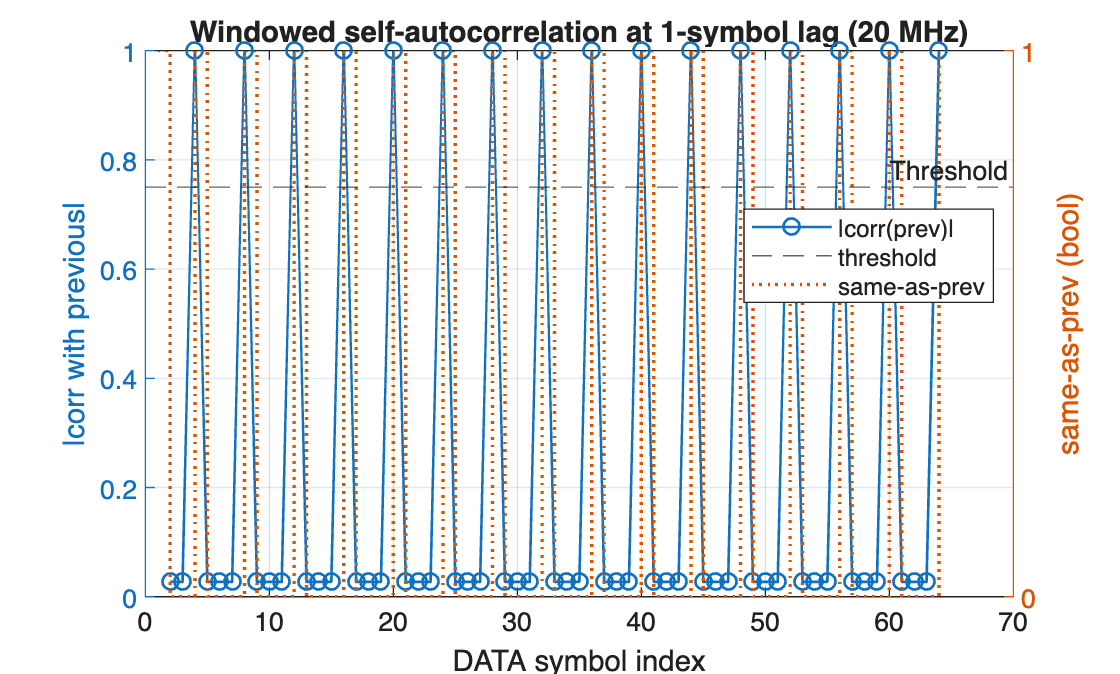


fig5_full = figure('Color','w','Name','FIGURE 5 — Autocorrelation (20 MHz)');
yyaxis left
plot(1:Ns, corrLag1_20, '-o','LineWidth',1); grid on; hold on
yline(th_same20,'--','Threshold');
xlabel('DATA symbol index'); ylabel('|corr with previous|');
title('Windowed self-autocorrelation at 1-symbol lag (20 MHz)');

yyaxis right
stairs(1:Ns, sameAsPrev20, ':','LineWidth',1.3);
ylim([0 1]); yticks([0 1]); ylabel('same-as-prev (bool)');
legend('|corr(prev)|','threshold','same-as-prev','Location','best');


% -----------------------------------------------------------------
% FIGURE 6: 5 MHz DETECTION DEMO (downsample by 4)
% -----------------------------------------------------------------

% Low-rate IoT RX view: decimate to 5 MHz (anti-aliased)
tx5   = decimate(tx, 4);                         % from signal processing toolbox
fs5   = fs/4;
sym5  = symSamp/4;                               % 80 -> 20 samples per symbol at 5 MHz

% Extract 5 MHz DATA slice
d5 = tx5(idxDATA(1)/4:idxDATA(2)/4);             
% Ensure an integer number of symbols
Ns5 = floor(numel(d5)/sym5);
d5  = d5(1:Ns5*sym5);                            % truncate cleanly
symMat5  = reshape(d5, sym5, Ns5);               % 64 symbol colmns with 20 rows of samples 

% autocorr at lag = 1 symbol 
% Normalize each symbol window 
norms    = sqrt(sum(abs(symMat5).^2, 1)) + eps;
W        = symMat5 ./ norms;                     % column-normalized
corrLag1 = nan(1, Ns5);                          % corr with previous
corrLag1(1) = NaN;                               
for k = 2:Ns5
    % inner product between current and previous symbol windows
    corrLag1(k) = abs( W(:,k-1)' * W(:,k) );
end

th_same     = 0.70;                              % threshold to determine if correlation is high enough
sameAsPrev  = corrLag1 >= th_same;               % NaN at k=1 stays false
sameAsPrev(1) = false;

% Simple SAME/DIFF decision for 5 MHz symbols
labels5 = repmat('A', 1, Ns5);   % array holding the detected symbols
for k = 2:Ns5
    if ~sameAsPrev(k)            % change detected -> toggle label
        labels5(k) = char('A' + ('B' - labels5(k-1)));
    else                         % same -> repeat previous label
        labels5(k) = labels5(k-1);
    end
end

fprintf("Symbol pattern detected with downsampling by 4: %s", labels5);

Symbol pattern detected with downsampling by 4: ABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABB

fprintf("do the Rx bits match the Tx bits(T=1, F=0): %d", strcmp(labels5, pattern));

do the Rx bits match the Tx bits(T=1, F=0): 1

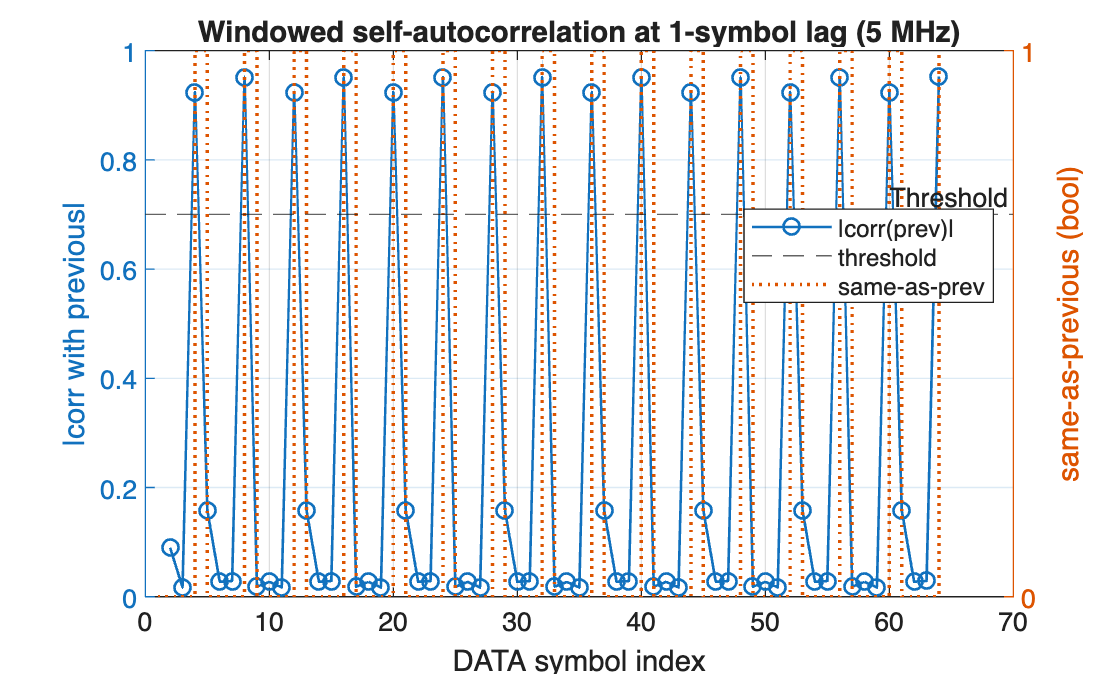


% Plot autocorr 
fig6 = figure('Color','w','Name','FIGURE 6 — Autocorrelation (5 MHz)');
yyaxis left
plot(1:Ns5, corrLag1, '-o','LineWidth',1); grid on; hold on
yline(th_same,'--','Threshold');
xlabel('DATA symbol index'); ylabel('|corr with previous|');
title('Windowed self-autocorrelation at 1-symbol lag (5 MHz)');

yyaxis right
stairs(1:Ns5, sameAsPrev, ':','LineWidth',1.3);
ylim([0 1]); yticks([0 1]); ylabel('same-as-previous (bool)');
legend('|corr(prev)|','threshold','same-as-prev','Location','best');


% -----------------------------------------------------------------
% FIGURE 7: 2.5 MHz DETECTION DEMO (downsample by 8)
% -----------------------------------------------------------------

tx25   = decimate(tx, 8);       
fs25   = fs/8;
sym25  = symSamp/8;                               % 80 -> 10 samples per symbol at 2.5 MHz

% Extract 2.5 MHz DATA slice
d25 = tx25(idxDATA(1)/8:idxDATA(2)/8);             
% Ensure an integer number of symbols
Ns25 = floor(numel(d25)/sym25);
d25  = d25(1:Ns25*sym25);                            % truncate cleanly
symMat25  = reshape(d25, sym25, Ns25);               % 64 symbol colmns with 10 rows of samples 

% autocorr at lag = 1 symbol 
% Normalize each symbol window 
norms    = sqrt(sum(abs(symMat25).^2, 1)) + eps;
W25        = symMat25 ./ norms;                   % column-normalized
corrLag2 = nan(1, Ns25);                          % corr with previous
corrLag2(1) = NaN;                               
for k = 2:Ns25
    % inner product between current and previous symbol windows
    corrLag2(k) = abs( W25(:,k-1)' * W25(:,k) );
end

th_same     = 0.50;                               % tune after plotting
sameAsPrev25  = corrLag2 >= th_same;               % NaN at k=1 stays false
sameAsPrev25(1) = false;

% Simple SAME/DIFF decision for 2.5 MHz symbols
labels25 = repmat('A', 1, Ns25);   % array holding the detected symbols
for k = 2:Ns25
    if ~sameAsPrev25(k)            % change detected -> toggle label
        labels25(k) = char('A' + ('B' - labels25(k-1)));
    else                           % same -> repeat previous label
        labels25(k) = labels25(k-1);
    end
end

fprintf("Symbol pattern detected with downsampling by 8: %s\n", labels25);

Symbol pattern detected with downsampling by 8: ABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABBABAABABB


fprintf("do the Rx bits match the Tx bits(T=1, F=0): %d", strcmp(labels25, pattern));

do the Rx bits match the Tx bits(T=1, F=0): 1

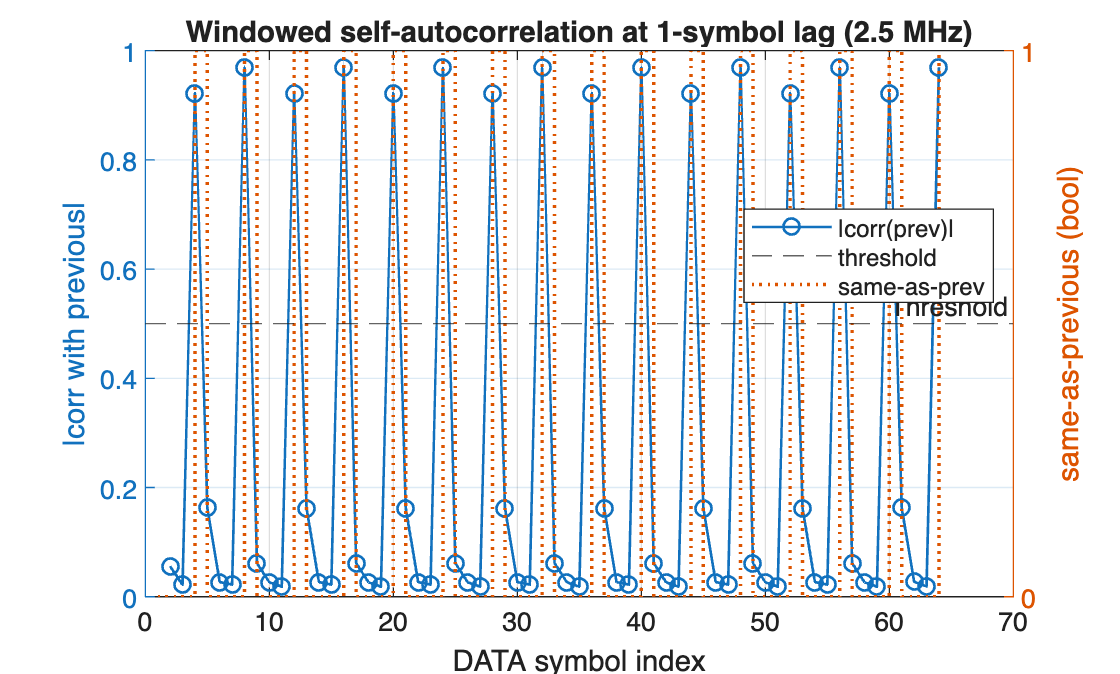


% Plot autocorr 
fig6 = figure('Color','w','Name','FIGURE 7 — Autocorrelation (2.5 MHz)');
yyaxis left
plot(1:Ns25, corrLag2, '-o','LineWidth',1); grid on; hold on
yline(th_same,'--','Threshold');
xlabel('DATA symbol index'); ylabel('|corr with previous|');
title('Windowed self-autocorrelation at 1-symbol lag (2.5 MHz)');

yyaxis right
stairs(1:Ns25, sameAsPrev25, ':','LineWidth',1.3);
ylim([0 1]); yticks([0 1]); ylabel('same-as-previous (bool)');
legend('|corr(prev)|','threshold','same-as-prev','Location','best');



% helper: inline "if" for chars
function y = ifelse(cond, a, b)
    if cond, y = a; else, y = b; end
end
